close all
clear all
clc

%% Import dati
opts=detectImportOptions('./data/MiniProjectEFSA.xlsx');
warning('OFF', 'MATLAB:table:ModifiedAndSavedVarnames')
data=readtable('./data/MiniProjectEFSA.xlsx', opts);
data.Properties.VariableNames={'response','numberOfAnimals','SD','dose','sex','endpoint'};

%% Subset Selection - endpoint 1
data_endpoint_1=data(data.endpoint==1,:);
gender_female_1 = categorical(data_endpoint_1.sex);
dose_1 = data_endpoint_1.dose;
response_1=data_endpoint_1.response;

weights_1= 1./((data_endpoint_1.SD./sqrt(data_endpoint_1.numberOfAnimals)).^2);

tbl1=table(response_1,dose_1,gender_female_1);

mdl_1 = stepwiselm(tbl1,'interactions','ResponseVar','response_1','Weights',weights_1,'Verbose',2)

   No candidate terms to add
   pValue for removing dose_1:gender_female_1 is 0.23004
1. Removing dose_1:gender_female_1, FStat = 2.0017, pValue = 0.23004
   No candidate terms to add
   pValue for removing dose_1 is 0.026742
   pValue for removing gender_female_1 is 8.8074e-06


mdl_1 = Linear regression model:
    response_1 ~ 1 + dose_1 + gender_female_1

Estimated Coefficients:
                         Estimate      SE       tStat       pValue  
                         ________    ______    _______    __________

    (Intercept)            551.84    13.447     41.039    1.6201e-07
    dose_1               -0.31284    0.1008    -3.1037      0.026742
    gender_female_1_1      -221.7    12.073    -18.363    8.8074e-06


Number of observations: 8, Error degrees of freedom: 5
Root Mean Squared Error: 1.25
R-squared: 0.986,  Adjusted R-Squared: 0.98
F-statistic vs. constant model: 171, p-value = 2.5e-05

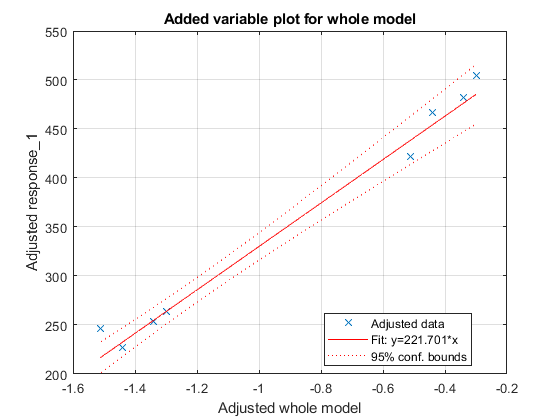


plot(mdl_1)
grid on

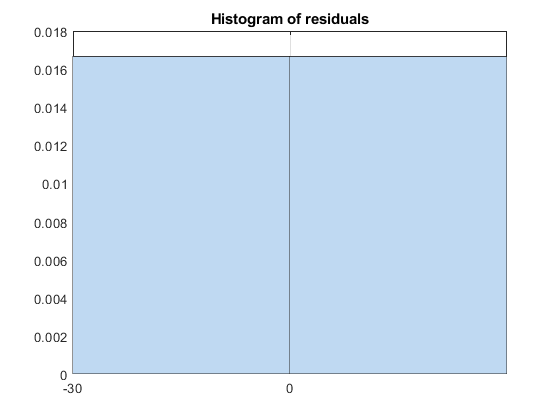

plotResiduals(mdl_1)
grid on

anova(mdl_1)

ans = 3×5 table
                       SumSq     DF    MeanSq      F         pValue  
                       ______    __    ______    ______    __________

    dose_1             15.032    1     15.032    9.6328      0.026742
    gender_female_1    526.22    1     526.22    337.21    8.8074e-06
    Error              7.8026    5     1.5605                        


coefCI(mdl_1)

ans =   517.2787  586.4103
   -0.5720   -0.0537
 -252.7355 -190.6660


%% Subset Selection - endpoint 2
data_endpoint_2=data(data.endpoint==2,:);
gender_female_2 = categorical(data_endpoint_2.sex);
dose_2 = data_endpoint_2.dose;
response_2=data_endpoint_2.response;

weights_2= 1./((data_endpoint_2.SD./sqrt(data_endpoint_2.numberOfAnimals)).^2);

tbl2=table(response_2,dose_2,gender_female_2);

mdl_2 = stepwiselm(tbl2,'ResponseVar','response_2','Weights',weights_2,'Verbose',2)

   pValue for adding dose_2 is 0.0026978
   pValue for adding gender_female_2 is 0.329
1. Adding dose_2, FStat = 24.057, pValue = 0.00269782
   pValue for adding gender_female_2 is 0.13488
   No candidate terms to remove


mdl_2 = Linear regression model:
    response_2 ~ 1 + dose_2

Estimated Coefficients:
                   Estimate        SE         tStat       pValue  
                   _________    _________    _______    __________

    (Intercept)       44.785      0.35731     125.34    1.7391e-11
    dose_2         -0.018754    0.0038235    -4.9048     0.0026978


Number of observations: 8, Error degrees of freedom: 6
Root Mean Squared Error: 1.37
R-squared: 0.8,  Adjusted R-Squared: 0.767
F-statistic vs. constant model: 24.1, p-value = 0.0027

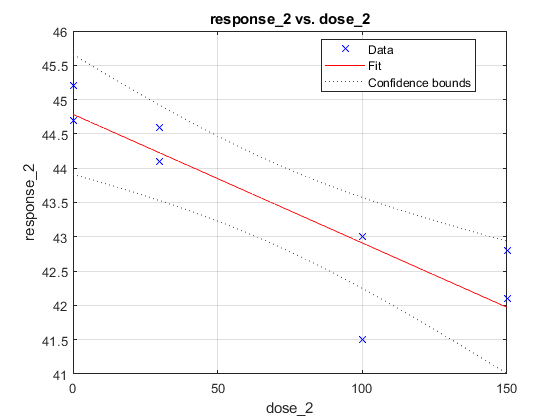


plot(mdl_2)
grid on

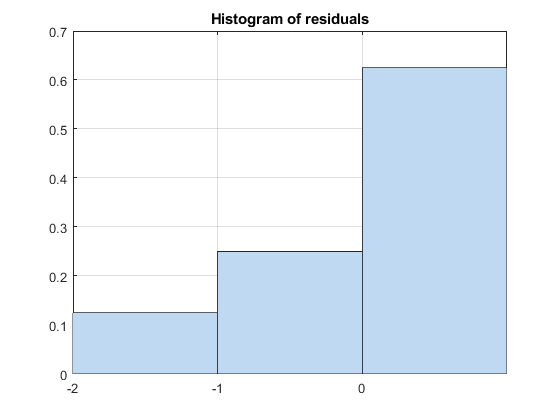

plotResiduals(mdl_2)
grid on

anova(mdl_2)

ans = 2×5 table
              SumSq     DF    MeanSq      F        pValue  
              ______    __    ______    ______    _________

    dose_2    45.309    1     45.309    24.057    0.0026978
    Error       11.3    6     1.8834                       


coefCI(mdl_2)

ans =    43.9110   45.6596
   -0.0281   -0.0094


%% Subset Selection - endpoint 3
data_endpoint_3=data(data.endpoint==3,:);
gender_female_3 = categorical(data_endpoint_3.sex);
dose_3 = data_endpoint_3.dose;
response_3=data_endpoint_3.response;

weights_3= 1./((data_endpoint_3.SD./sqrt(data_endpoint_3.numberOfAnimals)).^2);

tbl3=table(response_3,dose_3,gender_female_3);

mdl_3 = stepwiselm(tbl3,'ResponseVar','response_3','Weights',weights_3,'Verbose',2)

   pValue for adding dose_3 is 0.021483
   pValue for adding gender_female_3 is 0.16405
1. Adding dose_3, FStat = 9.5266, pValue = 0.021483
   pValue for adding gender_female_3 is 0.00053962
2. Adding gender_female_3, FStat = 61.5723, pValue = 0.000539623
   pValue for adding dose_3:gender_female_3 is 0.43244
   pValue for removing dose_3 is 0.00011858


mdl_3 = Linear regression model:
    response_3 ~ 1 + dose_3 + gender_female_3

Estimated Coefficients:
                         Estimate        SE       tStat       pValue  
                         _________    ________    ______    __________

    (Intercept)             18.219     0.12543    145.25     2.934e-10
    dose_3               -0.013887    0.001287    -10.79    0.00011858
    gender_female_3_1       1.0881     0.13867    7.8468    0.00053962


Number of observations: 8, Error degrees of freedom: 5
Root Mean Squared Error: 1.15
R-squared: 0.971,  Adjusted R-Squared: 0.959
F-statistic vs. constant model: 83.6, p-value = 0.000144

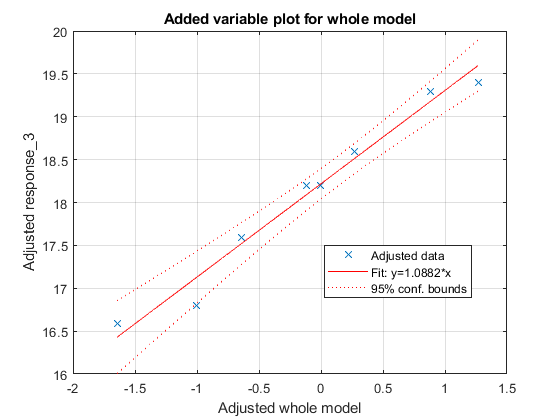


plot(mdl_3)
grid on

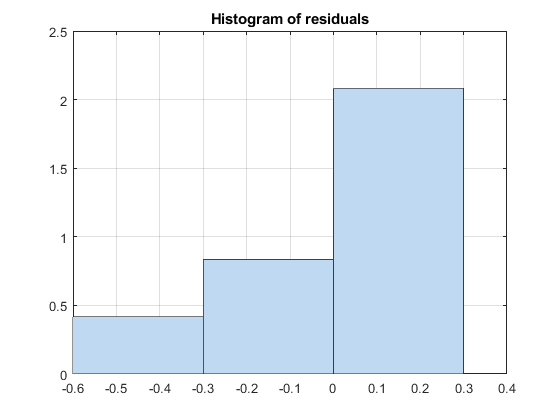

plotResiduals(mdl_3)
grid on

anova(mdl_3)

ans = 3×5 table
                       SumSq     DF    MeanSq      F         pValue  
                       ______    __    ______    ______    __________

    dose_3              155.2    1      155.2    116.43    0.00011858
    gender_female_3    82.078    1     82.078    61.572    0.00053962
    Error              6.6651    5      1.333                        


coefCI(mdl_3)

ans =    17.8962   18.5410
   -0.0172   -0.0106
    0.7317    1.4446
